# 车载360°鱼眼环视图像标定及拼接

Author: cuixingxing 

Email: cuixingxing150@gmail.com

Date: 2022.9.27

本教程实现了车载4副鱼眼环视图像标定过程和360度环视图像拼接，其中相机标定过程目的是为了得到每个相机的内外参，内参估计由畸变表格数据计算，四个相机都一样，外参估计由地面已知任意"矩形"物体物理尺寸宽度推算。随后根据此估计参数对4副鱼眼图像进行了360度全景拼接。可以直接运行此脚本体验整个过程。

## Requirements 

MathWorks Products ([https://www.mathworks.com](https://www.mathworks.com/))

- MATLAB R2022b or later

- Automated Driving Toolbox™

- Image Processing Toolbox™

- Computer Vision Toolbox™

Optional Products([opencv-python · PyPI](https://pypi.org/project/opencv-python/))

- opencv-python

## 读取数据及预览

### 畸变图像

根据提供的车载四幅鱼眼环视畸变图像导入到工作空间进行预览，以“Front”,"Left","Back","Right"为顺序。

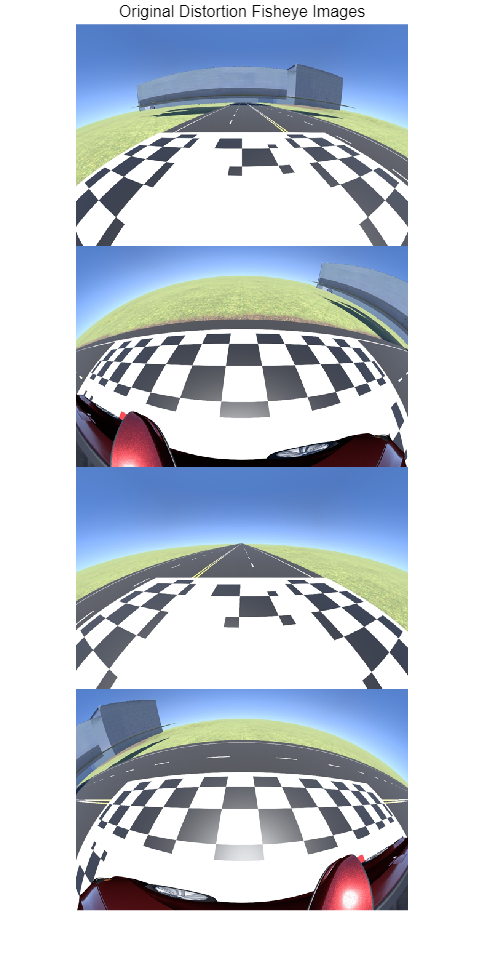

srcRoot = "./data/rectify_table_from_factory/fisheyeSurroundImages";
imageNames = ["front.jpg","left.jpg","back.jpg","right.jpg"];% 所有环视畸变图像

numImgs = length(imageNames);
oriImages = cell(1,numImgs);
for i = 1:numImgs
    oriImages{i} = imread(fullfile(srcRoot,imageNames(i)));% 假设数组大小都一样
end
montage(oriImages,Size=[numImgs,1])
title("Original Distortion Fisheye Images")

### 畸变表格

同样，导入畸变表格数据并进行预览：

cameraParaPath = "./data/rectify_table_from_factory/AT106K-DISTORTION.xlsx";
sensorRatio = 0.003;% 由厂家提供，单位 mm/pixel

cameraData = readtable(cameraParaPath,Range="A3:C977");% 第一列为入射角，单位：度，第二列为理想参考投影长度,单位：mm，第三列为实际畸变量长度，单位：mm
cameraData.Properties.VariableNames = ["angleIn","refHeight","realHeight"];
head(cameraData) % 预览畸变表格数据前面若干行

    angleIn    refHeight    realHeight
    _______    _________    __________
      0.1      0.0016675    0.0016675 
      0.2       0.003335     0.003335 
      0.3      0.0050026    0.0050026 
      0.4      0.0066702    0.0066701 
      0.5      0.0083378    0.0083376 
      0.6       0.010005     0.010005 
      0.7       0.011673     0.011673 
      0.8       0.013341      0.01334 


## 估计内参

鱼眼内参由内参矩阵$K$和畸变系数组成，本节采用KB模型(即OpenCV鱼眼模型)，另外关于图像去畸变方法有多种，此处直接利用厂家提供的畸变表格数据做数据拟合得到KB模型的四个畸变系数。

focal = mean(cameraData.refHeight./tand(cameraData.angleIn));% 焦距，单位:mm
[h,w,~] = size(oriImages{1});
K = [focal/sensorRatio,0,w/2;
    0,focal/sensorRatio,h/2;
    0,0,1];% 厂家提供的矫正表，其相机principle point位于图像中心。

r_d = 1./focal*cameraData.realHeight;% 求归一化平面上的r_d
thetaRadian = deg2rad(cameraData.angleIn);% 度数转为弧度
A = [thetaRadian.^3,thetaRadian.^5,thetaRadian.^7,thetaRadian.^9];
b = r_d-thetaRadian;
opencvCoeffs = A\b;
disp("最小二乘拟合OpenCV鱼眼模型畸变系数为(k1~k4)："+strjoin(string(opencvCoeffs'),","))

最小二乘拟合OpenCV鱼眼模型畸变系数为(k1~k4)：0.11453,-0.031552,0.010707,-0.0020925


*注：自R2024a可以使用内建`*[*cameraIntrinsicsKB*](https://ww2.mathworks.cn/help/vision/ref/cameraintrinsicskb.html)*`模型，但下面3行示例代码无法得到畸变图像到无畸变图像转换的映射矩阵mapX,mapY,以及任意指定输出FOV、输出图像大小，故当时自己实现`**initUndistortRectifyMapOpenCV**`函数。*

为控制输出的无畸变图像的视场角FOV，通过变量`FOVCoff`改变焦距从而改变FOV，输出图像大小通过变量`newImageSize`指定。

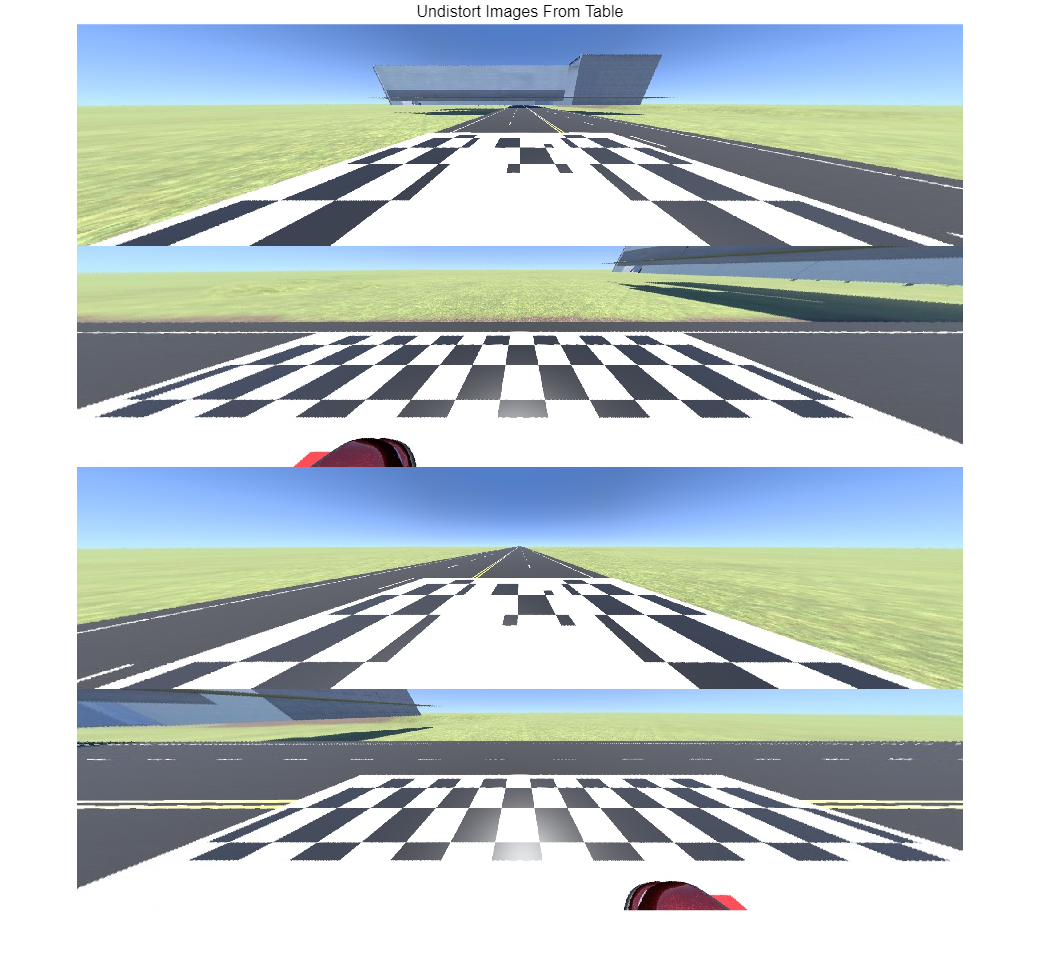

FOVCoff= 1;
newCameraMatrixK = [FOVCoff*K(1,1),0,K(1,3);
    0,FOVCoff*K(2,2),K(2,3);
    0,0,1];
newImageSize = [800,3200];% 期望输出图像大小，[height,width]，考虑到有共视区，把宽取大一点
[mapX,mapY] = initUndistortRectifyMapOpenCV(K, opencvCoeffs,newCameraMatrixK,newImageSize);

% undistort for every fisheye image
undistortImages = cell(1,numImgs);
for i = 1:numImgs
    undistortImages{i} = images.internal.interp2d(oriImages{i},mapX,mapY,"linear",100, false);
end
montage(undistortImages)
title("Undistort Images From Table")

上述是通过畸变表格数据估计了鱼眼相机的内参，如若改用棋盘格点估计内参+外参，但遗憾的是Matlab内建函数`detectCheckerboardPoints`和OpenCV内建函数`findChessboardCorners`均不容易检测到上述棋盘角点！无论是检测畸变图像还是无畸变图像，比如下面代码检测无畸变图像均失败。

故要正确方便的进行外参估计，不再采用传统检测棋盘格点的方式，改为下一节利用道路几何尺寸(由于目前提供的标定图像“Left”,"Right"视角难以找到道路几何宽度尺寸，故干脆所有视角图像中以棋盘宽度代替)的方法。

## 估计外参

上一节得到了无畸变图像`undistortImages`，要估计外参，这里引用一种直接通过地面已知物理尺寸的矩形的宽即可估计，优点是无需检测角点坐标，而且也可以利用道路车道线宽度也可以达到外参估计的目的！

首先分别为“Front”,"Left","Back","Right"四幅环视鱼眼指定要保存的外参参数（方便再次运行复现）、地面任意矩形物理尺寸宽度；其次，在显示的图像上交互绘制地面该矩形（在图像上表现为四边形梯形）`[drawpolygon](https://www.mathworks.com/help/images/ref/drawpolygon.html?s_tid=doc_ta)`，注意绘制的矩形宽度物理尺寸要与变量`rectangleWidths`分别与其中每个变量对应；最后，通过`[estimateMonoCameraFromScene](https://www.mathworks.com/help/driving/ref/estimatemonocamerafromscene.html?s_tid=doc_ta)`函数直接估计相机外参。

分别得到每个鱼眼相机的外参后，就可以直接利用这些参数计算单应矩阵/透视矩阵，从而转为Bird-Eye-View俯视图像了，为方便起见，这里继续利用了`[monoCamera](https://www.mathworks.com/help/driving/ref/monocamera.html?s_tid=doc_ta)`、`[birdsEyeView](https://www.mathworks.com/help/driving/ref/birdseyeview.html?s_tid=doc_ta)`等内建函数，优点是开箱即用，稳定可靠。当然自己也可以手写这些函数的实现，只不过没系统函数这些优势，懂原理即可。

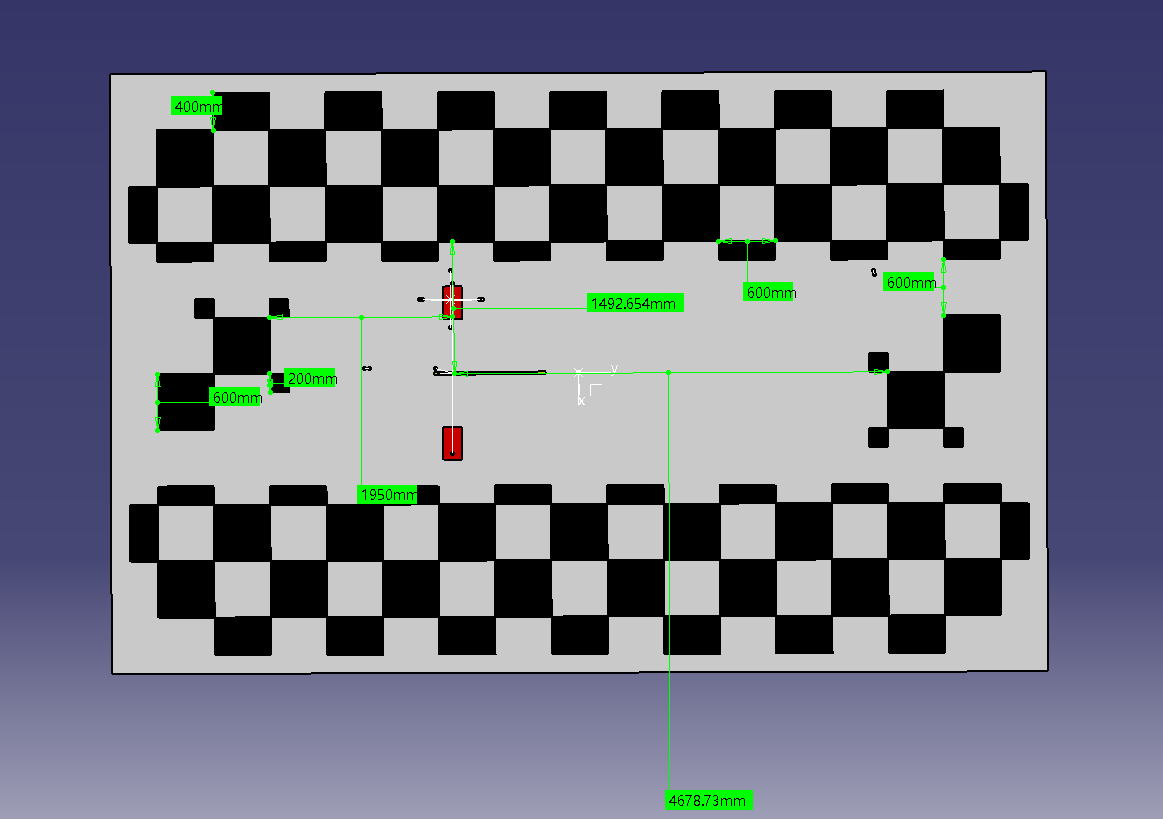

棋盘标定板“chessBoardDimension.png“物理尺寸，实际汽车位于图像中间并朝向左侧

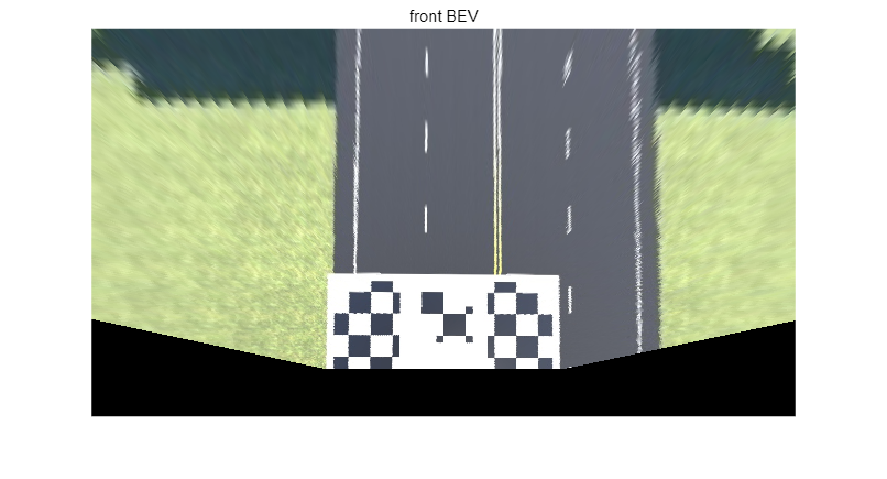

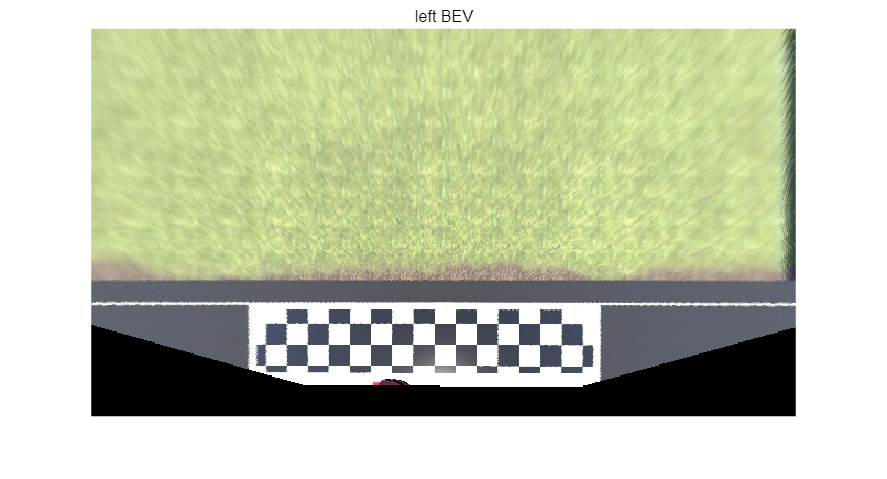

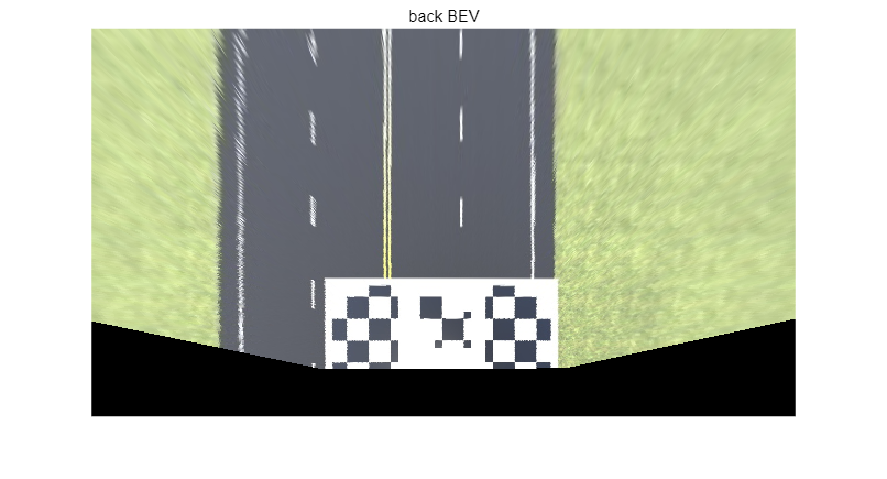

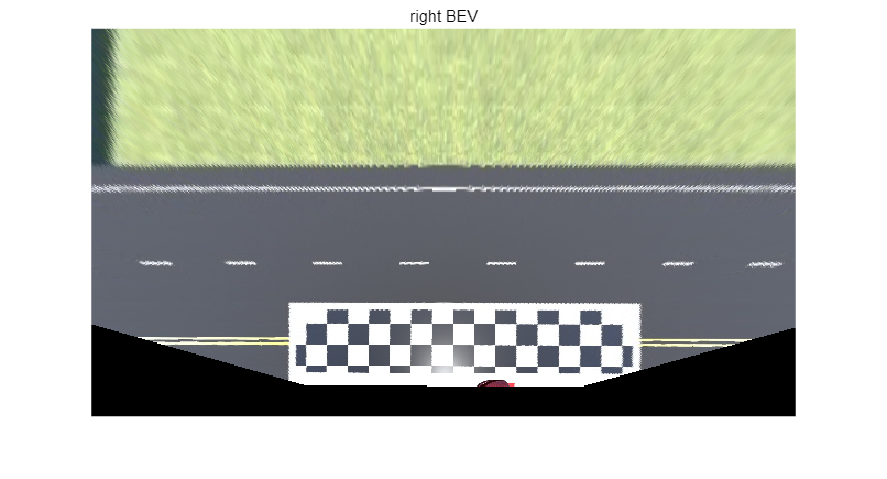

files = ["birdsEyeExtrinsicFront.mat","birdsEyeExtrinsicLeft.mat","birdsEyeExtrinsicBack.mat","birdsEyeExtrinsicRight.mat"];
matFiles = fullfile("./data/preSavedData",files);
rectangleWidths = [5.3853,9.0,5.3853,9.0];% 根据chessBoardDimension.png说明计算与手绘矩形有关，单位：米
BEV = cell(1,numImgs);
birdsEye = cell(1,numImgs);
for i = 1:numImgs
    undistortedImg = undistortImages{i};
    if ~isfile(matFiles(i)) % 避免反复手动绘制，没有则重新绘制已知ROI宽度和高度的信息即可
        figure;imshow(undistortedImg);
        title("Adjust the trapezoid ROI to select rectangular lane region, press Enter to continue");
        vertices = [size(undistortedImg,2)/2 size(undistortedImg,1)/2;...
            size(undistortedImg,2)/2 size(undistortedImg,1)*3/4;...
            size(undistortedImg,2)*3/4 size(undistortedImg,1)*3/4;...
            size(undistortedImg,2)*3/4 size(undistortedImg,1)/2];
        roi = drawpolygon(Position=vertices,FaceAlpha=0.2,LineWidth=1);

        % Wait until Enter is pressed
        wasButtonPressed = false;
        while ~wasButtonPressed
            wasButtonPressed = waitforbuttonpress;
            if double(get(gcf,"currentcharacter")) ~= 13
                wasButtonPressed = false;
            end
        end

        rectangleWidth = rectangleWidths(i);% 根据chessBoardDimension.png说明计算，单位：米
        imageSize = size(undistortedImg,[1,2]);
        focalLen = [newCameraMatrixK(1,1),newCameraMatrixK(2,2)];
        instrinsicIn = cameraIntrinsics(focalLen,imageSize(2:-1:1)/2,imageSize);
        [pitch,yaw,roll,height,intrinsicsOut] = estimateMonoCameraFromScene(roi.Position,rectangleWidth,instrinsicIn);


        % 无畸变图转BEV
        % 利用上述估计的镜头内外参数，构建birdsEyeView对象，其本质上就是个保存相机内外参和一些鸟瞰图预定义超参的结构体，方便做鸟瞰图投影，设置好自己想看到的可视范围outView和图像大小outImageSize，然后对无畸变图undistortedImg直接做俯视投影，即为BEV图像。
        sensor = monoCamera(intrinsicsOut,height,Pitch=pitch,Roll=roll,Yaw=yaw);
        distAhead = 10;% 前置摄像头光心到前面距离10m可视化范围内
        spaceToOneSide = 10;% 前置摄像头两侧各偏置10m可视化
        bottomOffset = -1;% 前置摄像头光心向后偏置1m可视化
        outView = [bottomOffset,distAhead,-spaceToOneSide,spaceToOneSide];
        outImageSize = [NaN,640];% 自定义图像宽度或者高度，其另一边自动推算，这个依赖指定的outVIew值
        birdsEyeT = birdsEyeView(sensor,outView,outImageSize);
        BEV{i} = transformImage(birdsEyeT,undistortedImg);
        birdsEye{i} = birdsEyeT;
        save(matFiles(i),"birdsEyeT");
    else
        s =  load(matFiles(i),"birdsEyeT");
        birdsEye{i} = s.birdsEyeT; 
        BEV{i} = transformImage(birdsEye{i},undistortedImg);
        
    end

    % show BEV image
    showName = char(imageNames(i));
    figure;imshow(BEV{i});title(showName(1:end-4)+" BEV")
end

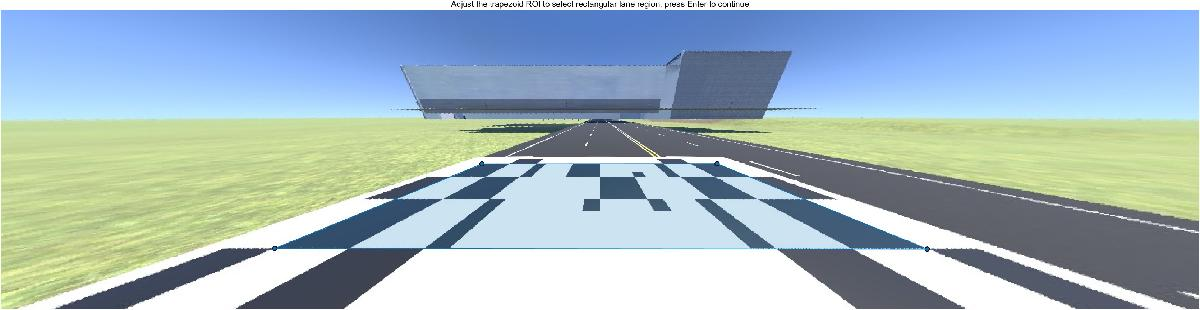

draw Front Trapezoid

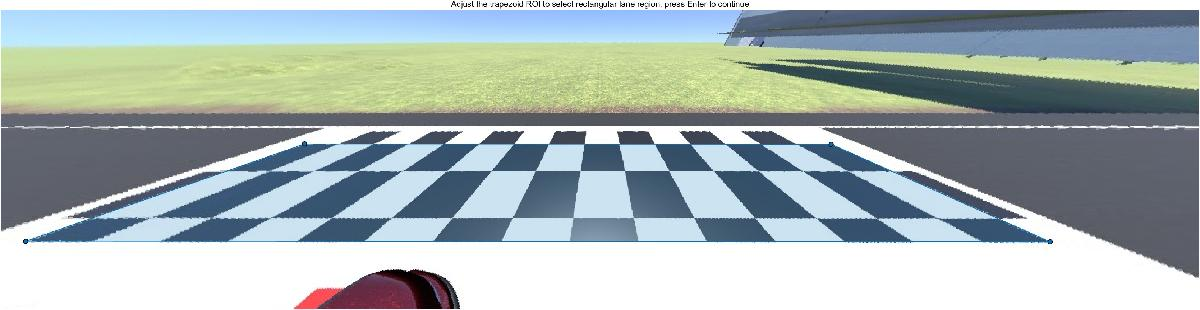

draw Left Trapezoid

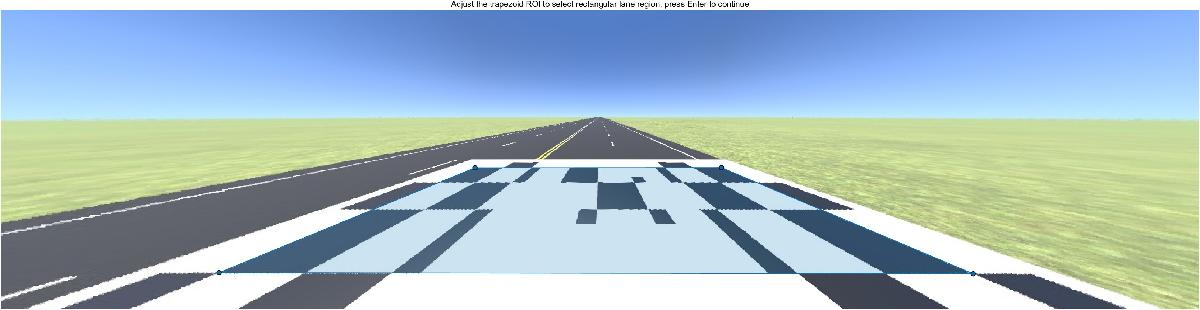

draw Back Trapezoid

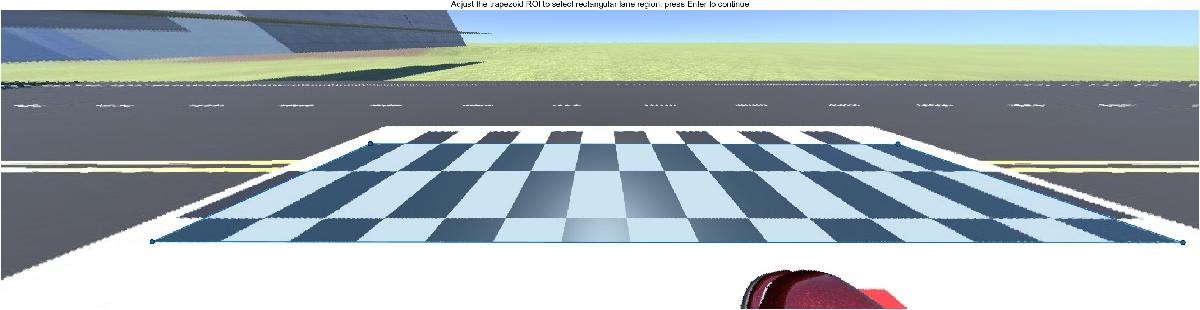

draw Right Trapezoid

## 估计对齐"Front"转换矩阵

由于缺乏有效匹配特征点，这里推荐利用内建交互工具`[cpselect](https://www.mathworks.com/help/images/ref/cpselect.html?s_tid=doc_ta)`函数可以手动选取控制匹配点对，每对图像选取十几个匹配点即可，选好/调整点位置后直接关闭窗口即可确认自动进入下一组图像，直到没有窗口自动弹出为止，这其中过程会分别计算front->front,left->front,back->front,right->front的2D刚性转换矩阵`tforms`。同样，为方便复现，指定了要保存的各类中间参数，再次运行可以加载参数复用。

isSelectControlPoints = false;
bev360File = "./data/preSavedData/birdsEye360.mat";
if isSelectControlPoints
    tforms = repmat(simtform2d(),1,numImgs);
    if isfile(bev360File) 
        load(bev360File,"selected*")
        % left->front
        [selectedMovingPoints1,selectedFixedPoints1] = cpselect(BEV{2},BEV{1},...
            selectedMovingPoints1,selectedFixedPoints1,'Wait',true);
        tforms(2) = fitgeotform2d(selectedMovingPoints1,selectedFixedPoints1,"similarity");
        
        % back->front
        [selectedMovingPoints2,selectedFixedPoints2] = cpselect(BEV{3},BEV{2},...
            selectedMovingPoints2,selectedFixedPoints2,'Wait',true);
        temp = fitgeotform2d(selectedMovingPoints2,selectedFixedPoints2,"similarity");
        tforms(3).A = tforms(2).A*temp.A;
        
        % right->front
        [selectedMovingPoints3,selectedFixedPoints3] = cpselect(BEV{4},BEV{1},...
            selectedMovingPoints3,selectedFixedPoints3,'Wait',true);
        tforms(4) = fitgeotform2d(selectedMovingPoints3,selectedFixedPoints3,"similarity");
        
        % fine-tune refine back->front tforms(3)
        [selectedMovingPoints4,selectedFixedPoints4] = cpselect(BEV{3},BEV{4},...
            selectedMovingPoints4,selectedFixedPoints4,'Wait',true);
        tform34 = fitgeotform2d(selectedMovingPoints4,selectedFixedPoints4,"similarity");
        tform31 = simtform2d(tforms(4).A*tform34.A);
    else
        % left->front
        [selectedMovingPoints1,selectedFixedPoints1] = cpselect(BEV{2},BEV{1},'Wait',true);
        tforms(2) = fitgeotform2d(selectedMovingPoints1,selectedFixedPoints1,"similarity");
        
        % back->front
        [selectedMovingPoints2,selectedFixedPoints2] = cpselect(BEV{3},BEV{2},'Wait',true);
        temp = fitgeotform2d(selectedMovingPoints2,selectedFixedPoints2,"similarity");
        tforms(3).A = tforms(2).A*temp.A;
        
        % right->front
        [selectedMovingPoints3,selectedFixedPoints3] = cpselect(BEV{4},BEV{1},'Wait',true);
        tforms(4) = fitgeotform2d(selectedMovingPoints3,selectedFixedPoints3,"similarity");
        
        % fine-tune refine back->front tforms(3)
        [selectedMovingPoints4,selectedFixedPoints4] = cpselect(BEV{3},BEV{4},'Wait',true);
        tform34 = fitgeotform2d(selectedMovingPoints4,selectedFixedPoints4,"similarity");
        tform31 = simtform2d(tforms(4).A*tform34.A);
    end
    
    scale = mean([tforms(3).Scale,tform31.Scale]);
    theta1 = tforms(3).RotationAngle;
    theta2 = tform31.RotationAngle;
    if theta1<0
        theta1 = theta1+360;
    end
    if theta2<0
        theta2 = theta2+360;
    end
    theta = mean([theta1,theta2]);
    t = mean([tforms(3).Translation;
        tform31.Translation]);
    tforms(3) = simtform2d(scale,theta,t);
    
    % 保存4个鱼眼相机各类参数,后续可直接拿任意同一时刻四张鱼眼图像做环视拼接
    save(bev360File,"mapX","mapY","birdsEye","tforms",...
        "selectedMovingPoints1","selectedFixedPoints1",...
        "selectedMovingPoints2","selectedFixedPoints2",...
        "selectedMovingPoints3","selectedFixedPoints3",...
        "selectedMovingPoints4","selectedFixedPoints4");
    
else
    load(bev360File,"tforms")
end


## 360度全景拼接

由上述四幅BEV图像和到”Front“基准转换的矩阵tforms，拼接360度地面环视图像，过渡区像素采用线性加权。

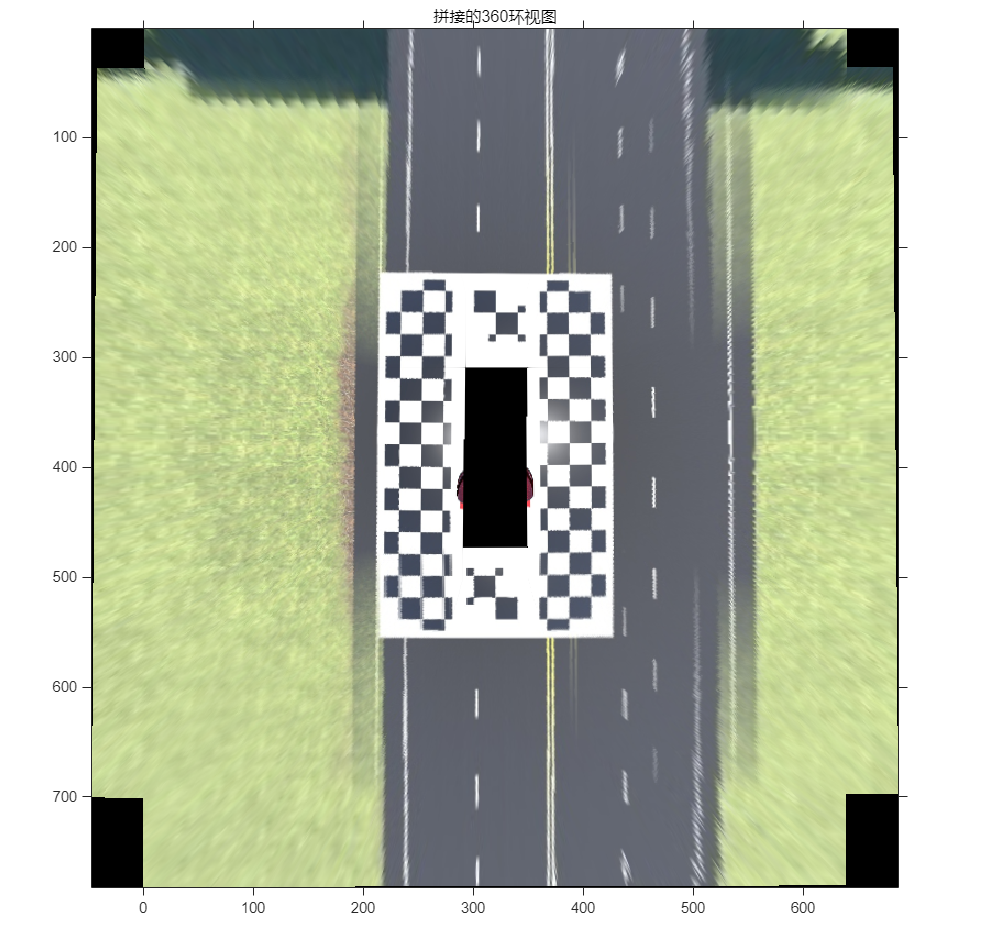

% 展示初始4张图像拼接效果
images = BEV;
tt = {tforms(1),tforms(2),tforms(3),tforms(4)};
[outputImage, outputView] = helperStitchImages(images,tt);
figure;imshow(outputImage,outputView)
title("拼接的360环视图")

## Support Functions

function [mapX,mapY,undistortPts, distortPts] = initUndistortRectifyMapOpenCV(K, opencvCoeffs,newCameraMatrixK,newImageSize)
% Brief: 由opencv鱼眼畸变系数得到映射和坐标点对应，功能等同于opencv的initUndistortRectifyMap函数
% Details:
%    None
% 
% Syntax:  
%     [mapX,mapY,undistortPts, distortPts] = initUndistortRectifyMapOpenCV(w, h, K, opencvCoeffs)
% 
% Inputs:
%    K - [3,3] size,[double] type,fisheye camera intrinsic,
%       [fx,0,cx;
%       0,fy,cy;
%       0,0,1] format
%    opencvCoeffs - [1,4] size,[double] type,opencv fisheye coeffs
%    newCameraMatrixK - [3,3] size,[double] type,new fisheye camera intrinsic,
%       [fx,0,cx;
%       0,fy,cy;
%       0,0,1] format
%    newImageSize - [1,2],[double] type,new image [height,width]
% 
% Outputs:
%    mapX - [h,w] size,[double] type,Description
%    mapY - [h,w] size,[double] type,Description
%    undistortPts - [h*w,2] size,[double] type,Description
%    distortPts - [h*w,2] size,[double] type,Description
% 
% Example: 
%   oriImg = imread("fishEye.png");
% 
%   % from opencv fisheye camera calibration results
%   opencvCoeffs = [-0.01078350003808737,0.04842806980013847,-0.04542399942874908,0.008737384341657162];  % mapping polynomial coefficients,[k1,k2,p1,p2]    
%   [h,w,c] = size(oriImg);
%   K = [286.7037963867188, 0, 413.3463134765625;
%       0, 286.7817993164062, 397.1785888671875;
%       0, 0, 1];
% 
%   [mapX,mapY] = initUndistortRectifyMapOpenCV(K,opencvCoeffs,K,[h,w]);
%   distortImg = im2double(distortImg);
%   undistortImg = images.internal.interp2d(distortImg,mapX,mapY,"linear",0, false);
%   figure;
%   imshow(undistortImg)
% 
% See also: None

% Author:                          cuixingxing
% Email:                           cuixingxing150@gmail.com
% Created:                         27-Sep-2022 09:42:05
% Version history revision notes:
%                        2022-11-23修改为支持自定义输入新内参矩阵和输出图像大小指定。
%                        2023-09-06修改变量命名，theta_d改为r_d,修改数值计算稳定性。
%                        2024-01-23修改以畸变中心为输出的正确尺寸大小。 
% Note:
%     1.Implement paper "opencv fisheye model by Juho Kannala and Sami Brandt."
%     2.入射角theta,畸变半径r_d都是针对单位成像平面计算的，最终目的得到scale,与实际成像平面成正比。
%
% Implementation In Matlab R2022a
% Copyright © 2022 TheMatrix.All Rights Reserved.
%
arguments 
    K (3,3) {mustBeNumeric}
    opencvCoeffs (1,4) {mustBeNumeric}
    newCameraMatrixK (3,3) {mustBeNumeric}
    newImageSize (1,2) {mustBeNumeric} % [rows,cols] format
end

% coeff convert to matlab
cx = round(newImageSize(2)/2);
cy = round(newImageSize(1)/2);
c0 = K(1,3);
c1 = K(2,3);
[undistortX,undistortY] = meshgrid(1-cx+c0:newImageSize(2)-cx+c0,1-cy+c1:newImageSize(1)-cy+c1);
undistortPts = [undistortX(:),undistortY(:)];

undistortPtsHomo = [undistortPts';
    ones(1,prod(newImageSize))]; % 3*cols size
undistortCameraPts = newCameraMatrixK\undistortPtsHomo; % 3*cols size
undistortCameraPts = undistortCameraPts./undistortCameraPts(end,:);% 3*cols size

r = vecnorm(undistortCameraPts(1:2,:),2,1); % 1*cols size
theta = atan(r);

r_d = theta.*(1+opencvCoeffs(1)*theta.^2+opencvCoeffs(2)*theta.^4+...
    opencvCoeffs(3)*theta.^6+opencvCoeffs(4)*theta.^8); % r_d非theta_d

r(r<=10^(-8))=1;
scale =r_d./r;
u = K(1,1)*undistortCameraPts(1,:).*scale+ K(1,3);
v = K(2,2)*undistortCameraPts(2,:).*scale + K(2,3);
distortPts = [u',v'];% rows*2

mapX = reshape(distortPts(:,1),newImageSize(1),newImageSize(2));
mapY = reshape(distortPts(:,2),newImageSize(1),newImageSize(2));
end

function [outputImage, outputView] = helperStitchImages(images, tforms) 
    % The helperStitchImages function applies the transforms tforms to the input images and blends 
    % them to produce the outputImage. It additionally returns the outputView, which you can use to 
    % transform any point from the first image in the given image sequence to the output image. 
    % Copyright 2021 MathWorks, Inc.
    
    numImages = numel(images);
    imageSize = zeros(numImages,2);
    xlim = zeros(numImages,2);
    ylim = zeros(numImages,2);
    
    % Compute the output limits for each transform.
    for i = 1:numImages
        imageSize(i,:) = size(images{i}, 1:2);
        [xlim(i,:), ylim(i,:)] = outputLimits(tforms{i}, ...
                                              [1 imageSize(i,2)], ...
                                              [1 imageSize(i,1)]);
    end    

    % Find the minimum and maximum output limits.
    xMin = min(xlim(:));
    xMax = max(xlim(:));

    yMin = min(ylim(:));
    yMax = max(ylim(:));

    % Width and height of panorama.
    width  = round(xMax - xMin);
    height = round(yMax - yMin);

    % Initialize the "empty" panorama.
    outputImage = zeros([height width 3], "uint8");

    % Create a 2-D spatial reference object defining the size of the panorama.
    xLimits = [xMin xMax];
    yLimits = [yMin yMax];
    
    outputView = imref2d([height width], xLimits, yLimits);

    % Step 7 - Stitch the images.
    for i = 1:numel(tforms)
        % Apply transformation.
        warpedImage = imwarp(images{i}, tforms{i},'linear','OutputView',outputView,'FillValues',0,'SmoothEdges',false);
        
        % Blend the images.
        outputImage = helperBlendImages(warpedImage, outputImage);
    end
end

function outputImage = helperBlendImages(I1, I2) 
%% The helperBlendImages function performs alpha blending to the given two input images, I1 and I2, 
% with alpha values that are proportional to the center seam of each image. 
% The output Iout is a linear combination of the input images:
% Iout = alpha * I1 + (1 - alpha) * I2

% Copyright 2021 MathWorks, Inc.


    % Identify the image regions in the two images by masking out the black
    % regions.
    maskA = sum(I1, 3) ~= 0;
    maskB = sum(I2, 3) ~= 0;
    maskAB = maskA & maskB;
    
    % Compute alpha values that are proportional to the center seam of the two
    % images.
    alpha1 = ones(size(maskA,1:2));
    alpha2 = ones(size(maskB,1:2));
    dist1  = bwdist(edge(maskA));
    dist2  = bwdist(edge(maskB));

    % alpha1,alpha2
    alpha1(maskAB) = dist1(maskAB)./(dist1(maskAB)+dist2(maskAB));
%     alpha1(maskB) = 0;

    alpha2(maskAB) = 1-alpha1(maskAB);
%     alpha2(maskA) = 0;

    I1 = double(I1);
    I2 = double(I2);        
    outputImage = alpha1.*I1 + alpha2.*I2;    
    outputImage = uint8(outputImage);
end



## References

-  Kannala, J., and S.S. Brandt. *A Generic Camera Model and Calibration Method for Conventional, Wide-Angle, and Fish-Eye Lenses.* IEEE Transactions on Pattern Analysis and Machine Intelligence 28, no. 8 (August 2006): 1335–40. [https://doi.org/10.1109/TPAMI.2006.153.](https://doi.org/10.1109/TPAMI.2006.153.)

- [Create 360° Bird's-Eye-View Image Around a Vehicle](https://www.mathworks.com/help/driving/ug/create-360-birds-eye-view-image.html)

- [Call Python from MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html)

- [深入洞察OpenCV鱼眼模型之成像投影和畸变表估计系数相互转化](https://github.com/cuixing158/OpenCVFisheyeAndDistortionTable)